Initialize variables for importing data

clc; clear all;
subject_num = 9010;
dof_type    = "drinking_task";
filepath = "C:/Git/FES_Exo/data/data_collection/S" + subject_num + "/" + dof_type + "/";

kp_val = 1.0;

fileset1 = dir(filepath + "*kp0.0*");
fileset2 = dir(filepath + "*kp" + num2str(kp_val) + "*");

start_time = 0.0; % time when movement starts that we want to look at

warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames') % supress warning for variable names
for i = 1:length(fileset1)
    T1{i} = readtable(filepath + fileset1(i).name);
    T1{i} = T1{i}(find(T1{i}.time_s_>=start_time,1):end,:);
    T1{i}.time_s_ = T1{i}.time_s_ - T1{i}.time_s_(1);
end

for i = 1:length(fileset2)
    T2{i} = readtable(filepath + fileset2(i).name);
    T2{i} = T2{i}(find(T2{i}.time_s_>=start_time,1):end,:);
    T2{i}.time_s_ = T2{i}.time_s_ - T2{i}.time_s_(1);
end

Combing through data to quantify features of data. Data collected here is:

- RMS Torque

- Max Torque

- RMS Error

for i = 1:length(T1)
    fes_share1(i)       = T1{i}.kp_val__(1);
    
    elbow_rms_torque1(i)    = rms(T1{i}.elbow_fe_trq_Nm_);
    forearm_rms_torque1(i)  = rms(T1{i}.forearm_ps_trq_Nm_);
    wrist_fe_rms_torque1(i) = rms(T1{i}.wrist_fe_trq_Nm_);
    wrist_ru_rms_torque1(i) = rms(T1{i}.wrist_ru_trq_Nm_);
    
    elbow_max_torque1(i)    = max(abs(T1{i}.elbow_fe_trq_Nm_));
    forearm_max_torque1(i)  = max(abs(T1{i}.forearm_ps_trq_Nm_));
    wrist_fe_max_torque1(i) = max(abs(T1{i}.wrist_fe_trq_Nm_));
    wrist_ru_max_torque1(i) = max(abs(T1{i}.wrist_ru_trq_Nm_));
    
    elbow_rms_error1(i)    = rms(T1{i}.com_elbow_fe_rad_   - T1{i}.act_elbow_fe_rad_);
    forearm_rms_error1(i)  = rms(T1{i}.com_forearm_ps_rad_ - T1{i}.act_forearm_ps_rad_);
    wrist_fe_rms_error1(i) = rms(T1{i}.com_wrist_fe_rad_   - T1{i}.act_wrist_fe_rad_);
    wrist_ru_rms_error1(i) = rms(T1{i}.com_wrist_ru_rad_   - T1{i}.act_wrist_ru_rad_);
end

for i = 1:length(T2)
    fes_share2(i)       = T2{i}.kp_val__(1);
    
    elbow_rms_torque2(i)    = rms(T2{i}.elbow_fe_trq_Nm_);
    forearm_rms_torque2(i)  = rms(T2{i}.forearm_ps_trq_Nm_);
    wrist_fe_rms_torque2(i) = rms(T2{i}.wrist_fe_trq_Nm_);
    wrist_ru_rms_torque2(i) = rms(T2{i}.wrist_ru_trq_Nm_);
    
    elbow_max_torque2(i)    = max(abs(T2{i}.elbow_fe_trq_Nm_));
    forearm_max_torque2(i)  = max(abs(T2{i}.forearm_ps_trq_Nm_));
    wrist_fe_max_torque2(i) = max(abs(T2{i}.wrist_fe_trq_Nm_));
    wrist_ru_max_torque2(i) = max(abs(T2{i}.wrist_ru_trq_Nm_));
    
    elbow_rms_error2(i)    = rms(T2{i}.com_elbow_fe_rad_   - T2{i}.act_elbow_fe_rad_);
    forearm_rms_error2(i)  = rms(T2{i}.com_forearm_ps_rad_ - T2{i}.act_forearm_ps_rad_);
    wrist_fe_rms_error2(i) = rms(T2{i}.com_wrist_fe_rad_   - T2{i}.act_wrist_fe_rad_);
    wrist_ru_rms_error2(i) = rms(T2{i}.com_wrist_ru_rad_   - T2{i}.act_wrist_ru_rad_);
end

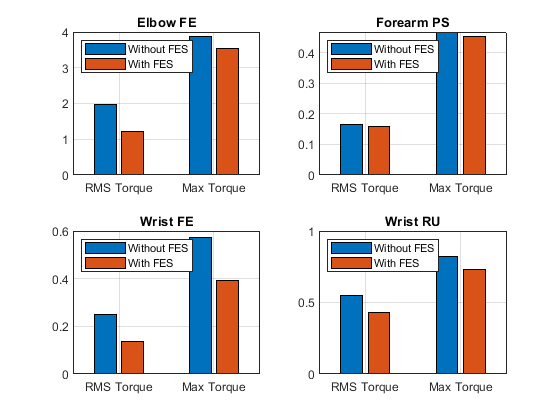

close all;
figure()
% Elbow
subplot(2,2,1)
data = [mean(elbow_rms_torque1), mean(elbow_rms_torque2);
        mean(elbow_max_torque1), mean(elbow_max_torque2)];
bar(data)
legend('Without FES','With FES','Location','northwest')
set(gca,'xticklabel',{'RMS Torque', 'Max Torque'})
title('Elbow FE')
grid on

% Forearm
subplot(2,2,2)
data = [mean(forearm_rms_torque1), mean(forearm_rms_torque2);
        mean(forearm_max_torque1), mean(forearm_max_torque2)];
bar(data)
legend('Without FES','With FES','Location','northwest')
set(gca,'xticklabel',{'RMS Torque', 'Max Torque'})
title('Forearm PS')
grid on

% Wrist FE
subplot(2,2,3)
data = [mean(wrist_fe_rms_torque1), mean(wrist_fe_rms_torque2);
        mean(wrist_fe_max_torque1), mean(wrist_fe_max_torque2)];
bar(data)
legend('Without FES','With FES','Location','northwest')
set(gca,'xticklabel',{'RMS Torque', 'Max Torque'})
title('Wrist FE')
grid on

% Wrist RU
subplot(2,2,4)
data = [mean(wrist_ru_rms_torque1), mean(wrist_ru_rms_torque2);
        mean(wrist_ru_max_torque1), mean(wrist_ru_max_torque2)];
bar(data)
legend('Without FES','With FES','Location','northwest')
set(gca,'xticklabel',{'RMS Torque', 'Max Torque'})
title('Wrist RU')
grid on

Formatting data so that it can be used for proper plotting including getting mean and std for the following features.

- RMS Torque

- Max Torque

- RMS Error

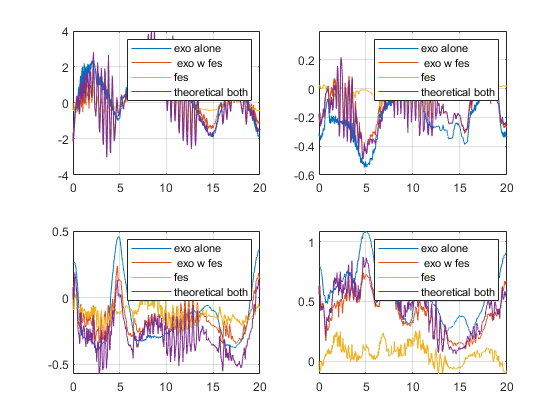

normal_comparison = 1;
diff_comparison = 2;

figure()
subplot(2,2,1);
plot(T1{normal_comparison}.time_s_,T1{normal_comparison}.elbow_fe_trq_Nm_); hold on
plot(T2{diff_comparison}.time_s_,T2{diff_comparison}.elbow_fe_trq_Nm_);
plot(T2{diff_comparison}.time_s_,T2{diff_comparison}.elbow_fe_fes_trq_Nm_);
plot(T2{diff_comparison}.time_s_,T2{diff_comparison}.elbow_fe_trq_Nm_+T2{diff_comparison}.elbow_fe_fes_trq_Nm_);
grid on
legend('exo alone', ' exo w fes', 'fes', 'theoretical both')

subplot(2,2,2);
plot(T1{normal_comparison}.time_s_,T1{normal_comparison}.forearm_ps_trq_Nm_); hold on
plot(T2{diff_comparison}.time_s_,T2{diff_comparison}.forearm_ps_trq_Nm_);
plot(T2{diff_comparison}.time_s_,T2{diff_comparison}.forearm_ps_fes_trq_Nm_);
plot(T2{diff_comparison}.time_s_,T2{diff_comparison}.forearm_ps_trq_Nm_+T2{diff_comparison}.forearm_ps_fes_trq_Nm_);
grid on
legend('exo alone', ' exo w fes', 'fes', 'theoretical both')

subplot(2,2,3);
plot(T1{normal_comparison}.time_s_,T1{normal_comparison}.wrist_fe_trq_Nm_); hold on
plot(T2{diff_comparison}.time_s_,T2{diff_comparison}.wrist_fe_trq_Nm_);
plot(T2{diff_comparison}.time_s_,T2{diff_comparison}.wrist_fe_fes_trq_Nm_);
plot(T2{diff_comparison}.time_s_,T2{diff_comparison}.wrist_fe_trq_Nm_+T2{diff_comparison}.wrist_fe_fes_trq_Nm_);
grid on
legend('exo alone', ' exo w fes', 'fes', 'theoretical both')

subplot(2,2,4);
plot(T1{normal_comparison}.time_s_,T1{normal_comparison}.wrist_ru_trq_Nm_); hold on
plot(T2{diff_comparison}.time_s_,T2{diff_comparison}.wrist_ru_trq_Nm_);
plot(T2{diff_comparison}.time_s_,T2{diff_comparison}.wrist_ru_fes_trq_Nm_);
plot(T2{diff_comparison}.time_s_,T2{diff_comparison}.wrist_ru_trq_Nm_+T2{diff_comparison}.wrist_ru_fes_trq_Nm_);
grid on
legend('exo alone', ' exo w fes', 'fes', 'theoretical both')

All plotting for paper

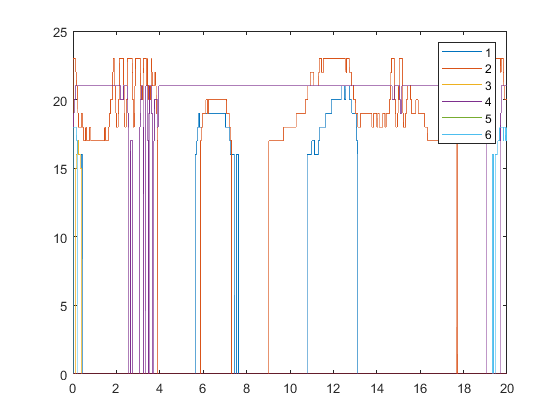

figure()
plot(T2{1}.time_s_,T2{1}.pw_0_us_); hold on
plot(T2{1}.time_s_,T2{1}.pw_1_us_);
plot(T2{1}.time_s_,T2{1}.pw_2_us_);
plot(T2{1}.time_s_,T2{1}.pw_3_us_);
plot(T2{1}.time_s_,T2{1}.pw_4_us_);
plot(T2{1}.time_s_,T2{1}.pw_5_us_);
plot(T2{1}.time_s_,T2{1}.pw_6_us_);
legend('1','2','3','4','5','6')

RMS torque plotting

figure()

titles = ["Elbow F/E", "Forearm P/S", "Wrist F/E", "Wrist R/U"];
means  = [elbow_rms_torque_mean;  forearm_rms_torque_mean; wrist_fe_rms_torque_mean; wrist_ru_rms_torque_mean];
stds   = [ elbow_rms_torque_std;   forearm_rms_torque_std;  wrist_fe_rms_torque_std; wrist_ru_rms_torque_std];

for i = 1:4
    subplot(2,2,i)
    errorbar(fes_percent,means(i,:),2*stds(i,:))
    title(titles(i))
    xlabel("c value")
    ylabel("RMS Torque (Nm)")
    grid on
end

Max torque plotting

figure()

titles = ["Elbow F/E", "Forearm P/S", "Wrist F/E", "Wrist R/U"];
means  = [elbow_max_torque_mean;  forearm_max_torque_mean; wrist_fe_max_torque_mean; wrist_ru_max_torque_mean];
stds   = [ elbow_max_torque_std;   forearm_max_torque_std;  wrist_fe_max_torque_std; wrist_ru_max_torque_std];

for i = 1:4
    subplot(2,2,i)
    errorbar(fes_percent,means(i,:),2*stds(i,:))
    title(titles(i))
    xlabel("c value")
    ylabel("Max Torque (Nm)")
    grid on
end

RMS Error plotting

figure()

titles = ["Elbow F/E", "Forearm P/S", "Wrist F/E", "Wrist R/U"];
means  = [elbow_rms_error_mean;  forearm_rms_error_mean; wrist_fe_rms_error_mean; wrist_ru_rms_error_mean];
stds   = [ elbow_rms_error_std;   forearm_rms_error_std;  wrist_fe_rms_error_std;  wrist_ru_rms_error_std];

for i = 1:4
    subplot(2,2,i)
    errorbar(fes_percent,rad2deg(means(i,:)),2*rad2deg(stds(i,:)))
    title(titles(i))
    xlabel("c value")
    ylabel("RMS error (deg)")
    grid on
end


Export data to run in R

variable_names = ["fes_share",...
                  "elbow_rms_torque", "forearm_rms_torque", "wrist_fe_rms_torque", "wrist_ru_rms_torque",...
                  "elbow_max_torque", "forearm_max_torque", "wrist_fe_max_torque", "wrist_ru_max_torque",...
                  "elbow_rms_error",  "forearm_rms_error",  "wrist_fe_rms_error",  "wrist_ru_rms_error"];

output_data = [fes_share',...
               elbow_rms_torque', forearm_rms_torque', wrist_fe_rms_torque', wrist_ru_rms_torque',...
               elbow_max_torque', forearm_max_torque', wrist_fe_max_torque', wrist_ru_max_torque',...
                elbow_rms_error',  forearm_rms_error',  wrist_fe_rms_error',  wrist_ru_rms_error']
            
output_table = array2table(output_data);
output_table.Properties.VariableNames = variable_names;

if dof_type == "single"
    output_table(17,:) = [];
end
writetable(output_table,dof_type + "_stats.csv")

Running T-Tests for data

for i = 1:length(stats)-1
    [   test_results.elbow_rms_torque_h(i),   test_results.elbow_rms_torque(i)] = ttest2(   stats{1}.elbow_rms_torque,   stats{i+1}.elbow_rms_torque,'Vartype',"unequal");
    [ test_results.forearm_rms_torque_h(i), test_results.forearm_rms_torque(i)] = ttest2( stats{1}.forearm_rms_torque, stats{i+1}.forearm_rms_torque,'Vartype',"unequal");
    [test_results.wrist_fe_rms_torque_h(i),test_results.wrist_fe_rms_torque(i)] = ttest2(stats{1}.wrist_fe_rms_torque,stats{i+1}.wrist_fe_rms_torque,'Vartype',"unequal");
    [test_results.wrist_ru_rms_torque_h(i),test_results.wrist_ru_rms_torque(i)] = ttest2(stats{1}.wrist_ru_rms_torque,stats{i+1}.wrist_ru_rms_torque,'Vartype',"unequal");
    
    [   test_results.elbow_max_torque_h(i),   test_results.elbow_max_torque(i)] = ttest2(   stats{1}.elbow_max_torque,   stats{i+1}.elbow_max_torque,'Vartype',"unequal");
    [ test_results.forearm_max_torque_h(i), test_results.forearm_max_torque(i)] = ttest2( stats{1}.forearm_max_torque, stats{i+1}.forearm_max_torque,'Vartype',"unequal");
    [test_results.wrist_fe_max_torque_h(i),test_results.wrist_fe_max_torque(i)] = ttest2(stats{1}.wrist_fe_max_torque,stats{i+1}.wrist_fe_max_torque,'Vartype',"unequal");
    [test_results.wrist_ru_max_torque_h(i),test_results.wrist_ru_max_torque(i)] = ttest2(stats{1}.wrist_ru_max_torque,stats{i+1}.wrist_ru_max_torque,'Vartype',"unequal");

    [   test_results.elbow_rms_error_h(i),   test_results.elbow_rms_error(i)] = ttest2(   stats{1}.elbow_rms_error,   stats{i+1}.elbow_rms_error,'Vartype',"unequal");
    [ test_results.forearm_rms_error_h(i), test_results.forearm_rms_error(i)] = ttest2( stats{1}.forearm_rms_error, stats{i+1}.forearm_rms_error,'Vartype',"unequal");
    [test_results.wrist_fe_rms_error_h(i),test_results.wrist_fe_rms_error(i)] = ttest2(stats{1}.wrist_fe_rms_error,stats{i+1}.wrist_fe_rms_error,'Vartype',"unequal");
    [test_results.wrist_ru_rms_error_h(i),test_results.wrist_ru_rms_error(i)] = ttest2(stats{1}.wrist_ru_rms_error,stats{i+1}.wrist_ru_rms_error,'Vartype',"unequal");
end


trying nonparametric instead

for i = 1:length(stats)-1
    [   test_results.elbow_rms_torque_h(i),   test_results.elbow_rms_torque(i)] = ranksum(   stats{1}.elbow_rms_torque,   stats{i+1}.elbow_rms_torque);
    [ test_results.forearm_rms_torque_h(i), test_results.forearm_rms_torque(i)] = ranksum( stats{1}.forearm_rms_torque, stats{i+1}.forearm_rms_torque);
    [test_results.wrist_fe_rms_torque_h(i),test_results.wrist_fe_rms_torque(i)] = ranksum(stats{1}.wrist_fe_rms_torque,stats{i+1}.wrist_fe_rms_torque);
    [test_results.wrist_ru_rms_torque_h(i),test_results.wrist_ru_rms_torque(i)] = ranksum(stats{1}.wrist_ru_rms_torque,stats{i+1}.wrist_ru_rms_torque);
    
    [   test_results.elbow_max_torque_h(i),   test_results.elbow_max_torque(i)] = ranksum(   stats{1}.elbow_max_torque,   stats{i+1}.elbow_max_torque);
    [ test_results.forearm_max_torque_h(i), test_results.forearm_max_torque(i)] = ranksum( stats{1}.forearm_max_torque, stats{i+1}.forearm_max_torque);
    [test_results.wrist_fe_max_torque_h(i),test_results.wrist_fe_max_torque(i)] = ranksum(stats{1}.wrist_fe_max_torque,stats{i+1}.wrist_fe_max_torque);
    [test_results.wrist_ru_max_torque_h(i),test_results.wrist_ru_max_torque(i)] = ranksum(stats{1}.wrist_ru_max_torque,stats{i+1}.wrist_ru_max_torque);

    [   test_results.elbow_rms_error_h(i),   test_results.elbow_rms_error(i)] = ranksum(   stats{1}.elbow_rms_error,   stats{i+1}.elbow_rms_error);
    [ test_results.forearm_rms_error_h(i), test_results.forearm_rms_error(i)] = ranksum( stats{1}.forearm_rms_error, stats{i+1}.forearm_rms_error);
    [test_results.wrist_fe_rms_error_h(i),test_results.wrist_fe_rms_error(i)] = ranksum(stats{1}.wrist_fe_rms_error,stats{i+1}.wrist_fe_rms_error);
    [test_results.wrist_ru_rms_error_h(i),test_results.wrist_ru_rms_error(i)] = ranksum(stats{1}.wrist_ru_rms_error,stats{i+1}.wrist_ru_rms_error);
end